# Button Grid

This widget provides an array of pushbutton controls that are grouped together. You provide an array of icons and/or text labels for the buttons. It has a single callback function that provides eventdata indicating which button was pushed.

Create a figure with a grid layout:

figObj = uifigure("Position",[100 100 250 250]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);
gridObj.RowHeight = {60};
gridObj.ColumnWidth = {'1x'};

Create and configure the widget:

buttonGridWidget = wt.ButtonGrid(gridObj);
buttonGridWidget.ButtonPushedFcn = @(src,evt)disp(evt);
buttonGridWidget.BackgroundColor = [.6 .8 1];

Add icons only

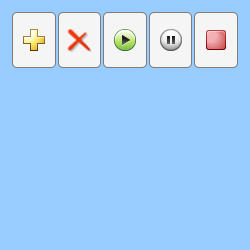

buttonGridWidget =   ButtonGrid with properties:

    ButtonPushedFcn: @(src,evt)disp(evt)

               Icon: ["add_24.png"    "delete_24.png"    "play_24.png"    "pause_24.png"    "stop_24.png"]
               Text: [1×0 string]
            Tooltip: [1×0 string]
          ButtonTag: [1×0 string]
       ButtonEnable: on
        Orientation: horizontal
      IconAlignment: top
        ButtonWidth: {'1x'  '1x'  '1x'  '1x'  '1x'}
       ButtonHeight: {'1x'}
        ButtonColor: [0.9600 0.9600 0.9600]

           Position: [11 181 230 60]
              Units: 'pixels'

  Show all properties


buttonGridWidget.Icon = [
    "add_24.png"
    "delete_24.png"
    "play_24.png"
    "pause_24.png"
    "stop_24.png"
    ]

Now add text and tooltips to the buttons

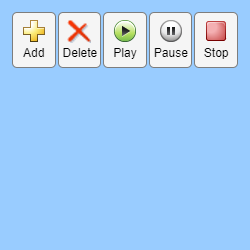

buttonGridWidget.Text = [
    "Add"
    "Delete"
    "Play"
    "Pause"
    "Stop"
    ];

buttonGridWidget.Tooltip = [
    "Press to Add"
    "Press to Delete"
    "Press to Play"
    "Press to Pause"
    "Press to Stop"
    ];

Make them vertical instead. The parent grid needs to be adjusted to accomodate the new format.

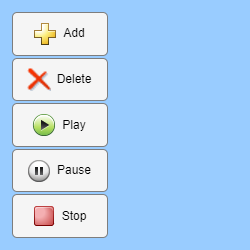

buttonGridWidget.Orientation = "vertical";
buttonGridWidget.IconAlignment = "left";
gridObj.RowHeight = {'1x'};
gridObj.ColumnWidth = {100};

*Copyright 2020-2025 The MathWorks, Inc.*